# Preprocessing Signal

Preprocessing Using Pan Tompkin

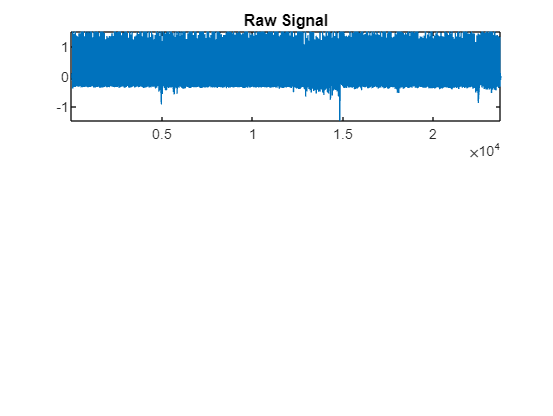

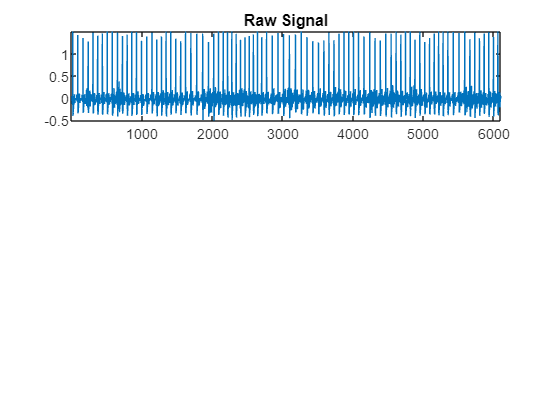

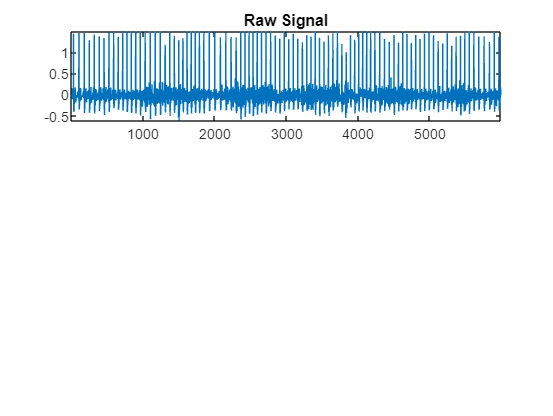

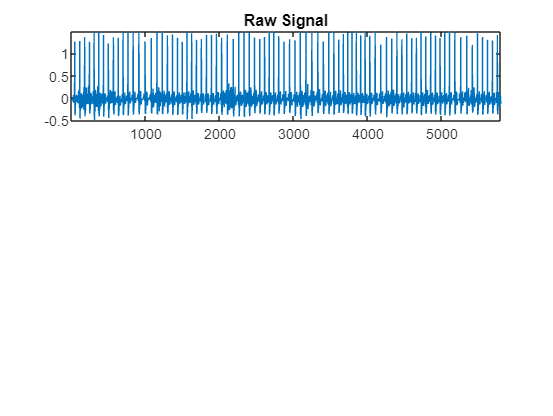

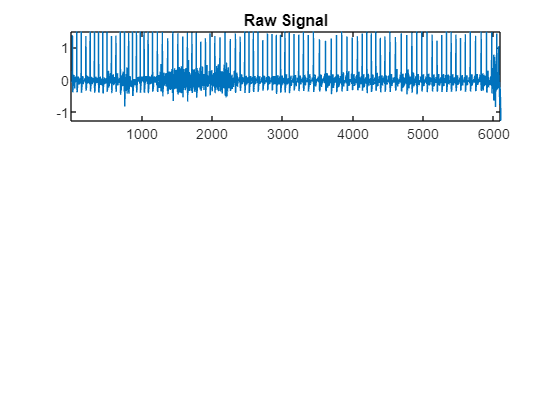

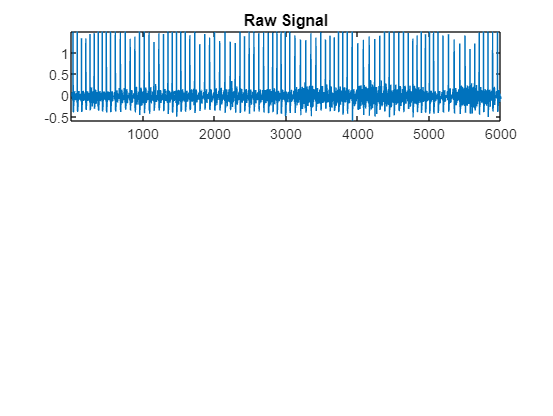

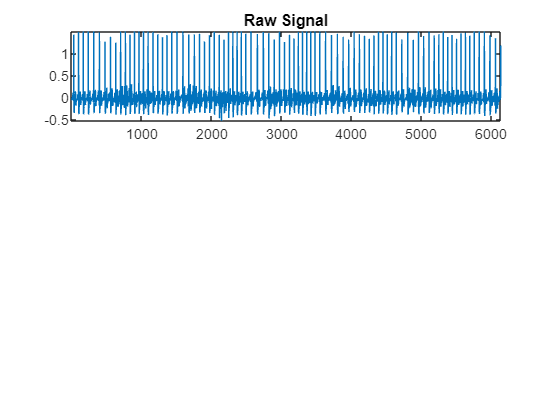

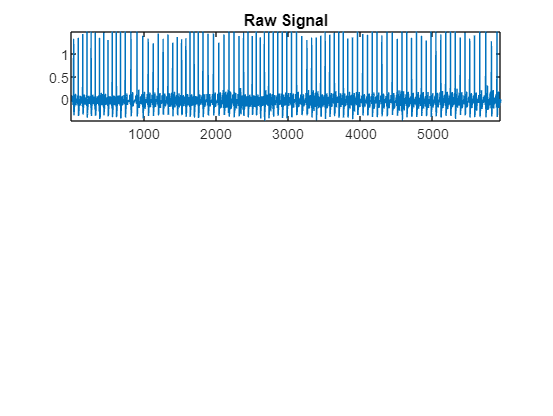

% Simpan semua matriks dalam cell array
all_clip = {baseline, clip1, clip2, clip3, clip4, clip5, clip6, clip7, clip8, clip9, clip10, clip11, clip12, clip13, clip14, clip15, clip16, rest}; 

% Preallocate cell array untuk hasil perhitungan
all_RR = cell(1, 19);

% Loop melalui setiap matriks dalam cell array
for idx = 1:length(all_clip)
    % Ambil matriks saat ini
    current_clip = all_clip{idx};
    
    % Preallocate array untuk hasil dari perhitungan pada current_matrix
    current_RR = zeros(1,1);  % Sesuaikan ukuran dengan current_clip
    
    
    % Lakukan operasi sesuai contoh Anda (pastikan batas indeks)
    [qrs_amp_raw,qrs_i_raw,delay]=pan_tompkin(current_clip,100, 0);

    %Convert index to time
    fs = 100;
    t = zeros(1,1);
    for k=1:size(qrs_i_raw,2)
        t(k,1) = qrs_i_raw(1,k)/fs;
    end

    %Searching for RR-Interval
    for m=1:size(t,1)-1
        current_RR(m,1) = abs(t(m+1,1) - t(m,1));
    end
    
    % Simpan hasilnya ke cell array result_data
    all_RR{idx} = current_RR;
end


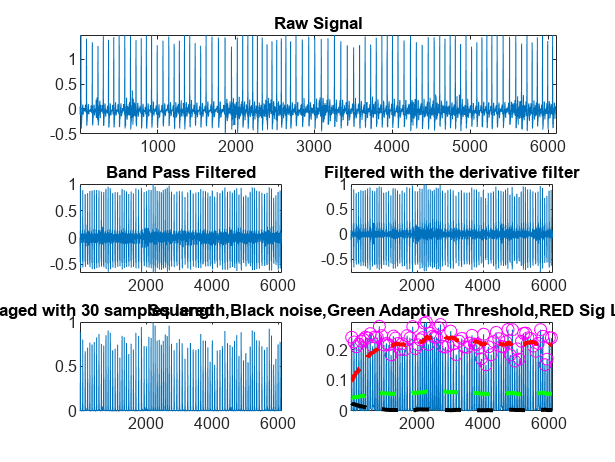

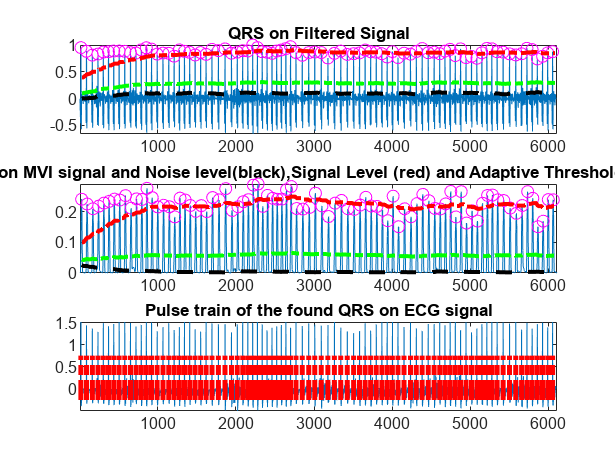

qrs_amp_raw =     0.9512    0.8831    0.8111    0.8302    0.8685    0.8756    0.8879    0.8871    0.8821    0.8577    0.8507    0.9086    0.9480    0.9240    0.8304    0.8493    0.8449    0.7911    0.9089    0.8823    0.8628    0.8137    0.8600    0.8245    0.9190    0.8952    0.9273    0.8475    0.8676    0.8940    0.8889    1.0000    0.9508    0.8738    0.8653    0.8441    0.8875    0.9070    0.9331    0.9686    0.8575    0.8087    0.8586    0.8681    0.8588    0.7574    0.8445    0.8872    0.8241    0.8381


qrs_i_raw =           13          84         159         231         300         366         433         503         575         648         718         786         851         918         990        1064        1139        1208        1274        1340        1407        1476        1547        1617        1692        1775        1860        1942        2017        2086        2152        2214        2275        2336        2398        2462        2522        2581        2639        2699        2769        2850        2932        3010        3093        3178        3261        3343        3426        3507


delay = 7.5000

[qrs_amp_raw,qrs_i_raw,delay]=pan_tompkin(clip1,100,1)

Convert Index to Time

fs = 100;
t = zeros(1,1);
for k=1:size(qrs_i_raw,2)
    t(k,1) = qrs_i_raw(1,k)/fs;
end

Searching for R-R Interval

RR = zeros(1,1);
for m=1:size(t,1)-1
    RR(m,1) = abs(t(m+1,1) - t(m,1));
end